clear;clc;close all
layerfolder='../data/layers/';%route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 8.577359 seconds.


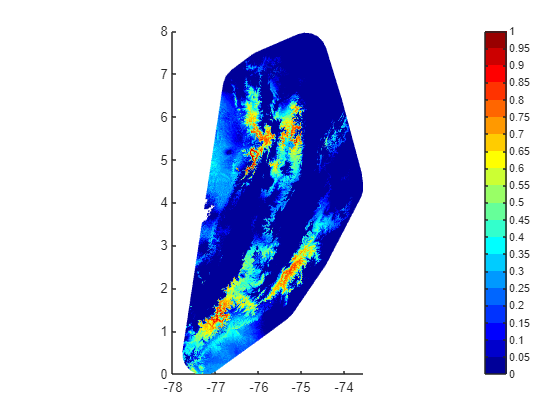

InfoInitialPoint = InitialPoint(Dimensions);
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

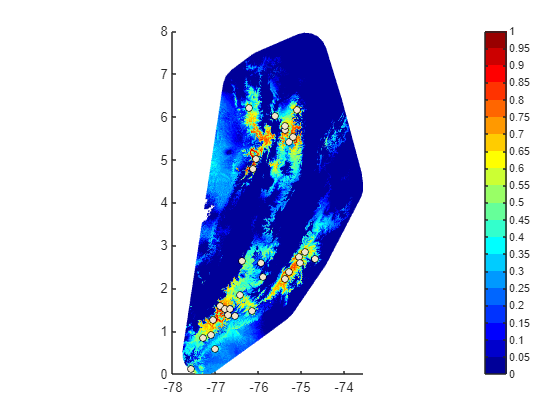

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 30, -3, true, 'GenSP', true, true);

close all
[data,outland] = bnm_prep(T, Dimensions, false, 0.7, false, false);

----Finding correlation----
Elapsed time is 0.822295 seconds.
----Creating predictors----
¡All done!
Elapsed time is 0.902935 seconds.


close all, clf
show=false;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=false;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
class = ColoringBorder(data,show,outlier,outlier2,0.5);

radius =     2.5177    1.9994    2.0654    1.8189    2.0210    2.4174    2.5704    2.6803
    1.1432    1.0135    1.5091    1.6090    1.1567    0.8317    0.9210    1.1207
    0.9001    1.4831    1.3232    1.8127    1.8495    1.1489    1.0726    1.4429
    2.5069    1.9190    1.9094    1.4965    1.9485    2.3084    2.5006    2.5439
    0.2768    0.9392    1.0674    1.5906    1.2603    0.6760    0.6027    0.9310
    0.7276    0.5525    1.0336    1.3624    0.7712    0.6790    0.8102    0.8076
    0.9221    0.4824    1.0326    1.1906    0.5581    0.6867    0.8655    0.8815
    2.3608    1.7236    1.6963    1.2376    1.5833    2.1307    2.3333    2.3076
    1.1998    0.6964    1.0588    1.0954    0.2787    0.9423    1.1076    1.0848
    1.1755    1.1953    1.2533    1.4782    0.9082    1.0039    1.0390    1.0522


radiusClass =     0.2768    0.4824    0.6477    0.7031    0.2787    0.5616    0.3467    0.6156


MapMetric(MapInfo.Map,class.map,false)

ans =     0.8613    0.7952


MapMetric(MapInfo.Map,dataf.Map,false)

ans =     0.7239    0.7866


newInfo = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 100, -3, true, 'GenSP', true, true);
[dataNew,outland] = bnm_prep(newInfo, Dimensions, false, 0.7, false, false);
newPoints(dataNew{1},class)

----Modeling----


ij = 1

-Model 1


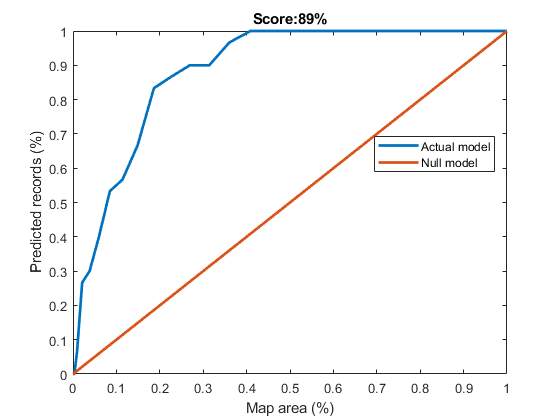

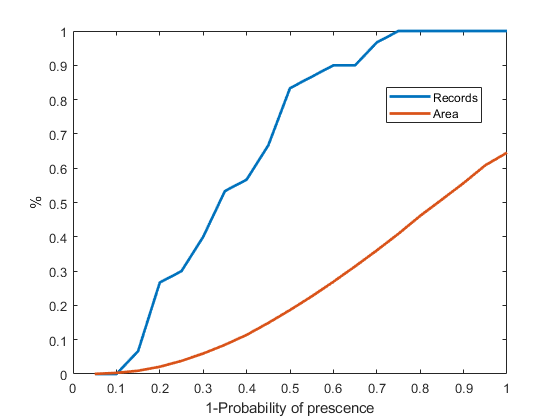

Elapsed time is 0.781987 seconds.


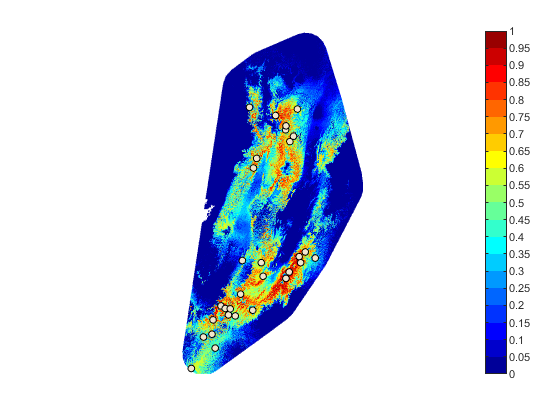

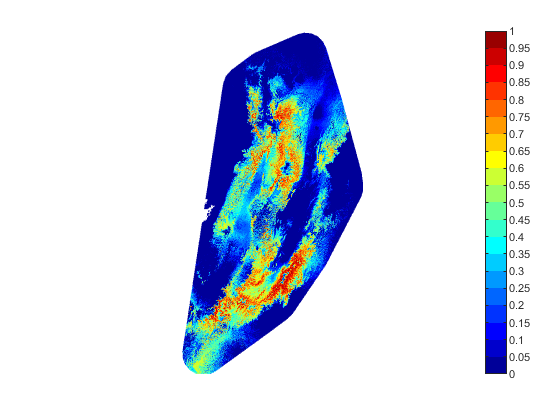

dataf = bnm_modeling(data, '', true, 4, false);

close all
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=true;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
data = bnm_modeling2(data{1},show,outlier,outlier2)